# **Explore 1-DOF Spring Mass Damper           **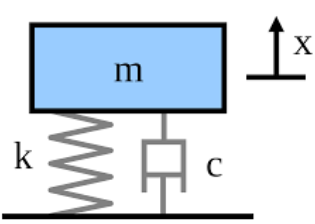

In this example we're going to study the single degree of freedom (dof)  mechanical system known as the "Spring Mass Damper".  There are 3 parameters for this 1-dof mechanical system:

$\qquad \bullet $ **m** is the spring mass (kg)

$\qquad 
\bullet $ **k** is the spring stiffness (N/m)

$\qquad 
\bullet $ **c** is the spring damping (N/(m/sec))  

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet $ derive the **NUMERICAL**  solution for an excitation force made up of a STEP function type input.

Finally we'll recommend that you explore the corresponding models developed in:

$\bullet $  Simulink,  and 

$\bullet $  Simscape.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

To derive the system's equation of motion, we assume that the system is in motion with positive displacement and velocity, and we then construct a free body diagram that shows all of the forces acting on the mass. This free body diagram looks like this:

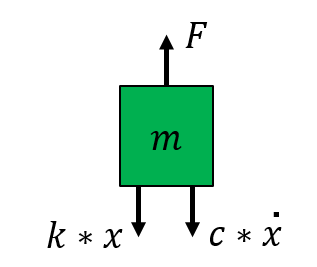

From this diagram we then apply Newton's law:  $m\thinspace\ddot{x} = \Sigma \enspace Forces$ .   

So for our system we would have:


$$m\thinspace.\thinspace\ddot{x}(t) = F -c \thinspace.\thinspace \dot{x}(t) - k \thinspace.\thinspace x(t)$$


Which can then be rearranged into the following form:


$$m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$$


The above 2nd order Ordinary Differential Equation (ODE) is referred to as the systems equation of motion. Our next step is to find the analytical solution to this 1-dof system.  This is a good exercise to do by hand.  To confirm your hand derived solution, let's get the ***Symbolic toolbox*** for MATLAB to solve it too !

We'll do this in two stages, first we'll look at the homogeneous case, ie: the case where there are NO excitation forces. Then we'll also solve the case where we do have some excitation forces - and specifically we'll look at STEP type input forces.

**Define the Mechanical system parameters:**

m = 1       % (kg)

m = 1

c = 2*0.2*3 % (N/(m/sec))

c = 1.2000

k = 9       % (N/m)

k = 9

**Define the system INITIAL conditions**

% define some INITIAL conditions
init_x    = 1;
init_xdot = 0;

# Numerical solution:

So far we've looked at finding an analytical solution to the mechanical 1-dof system. An alternate approach is to solve the problem numerically. This numerical approach is extremely attractive when an analytical solution becomes difficult and/or impossible to derive.  At the heart of this approach are MATLAB's ODE solver suite - MATLAB has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .

These numeric ODE solvers require you to package your problem into a 1st order form. We'll discuss how to do this in more detail in the next tutorial (on 2-dof systems), but for the moment here's a quick summary of the form that we need to package our problem into.  We consider the general *n-dof* case:  $M \ddot{X} + C\dot{X} + KX = F$  where $X \in R^{n\times1}$

And then we repackage it into this form:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which we can abbreviate to:

                  $\dot{Z} = A \times Z + G$    where:  

- $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So the new 1st order system described above, is the form that we can now send to MATLAB's Numerical ODE solver suite. Let's look at an example. Specifically we'll look at the systems response to a STEP type input force. Specifically, our F(t) will be:

- $F\left(t\right)=3\ldotp u\left(t-15\right)$   where u(t) is the UNIT STEP function (aka the HEAVISIDE function)

% Define your INITIAL conditions
z_init = [ init_xdot ;
           init_x    ;  ];
       
% define the system EXCITATION function
F         = @(t) 3*heaviside(t-15);

% define the 1st order system to solve
A         = [-c/m, -k/m;  
                1,   0];

G         = @(t) ( [ F(t)/m ;  
                     0; ]  );  
                 
MY_SYSTEM = @(t, z) (A*z + G(t));

% Define some ODE solver settings
t_span     = [0 20];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);


## Plot the NUMERIC solution:

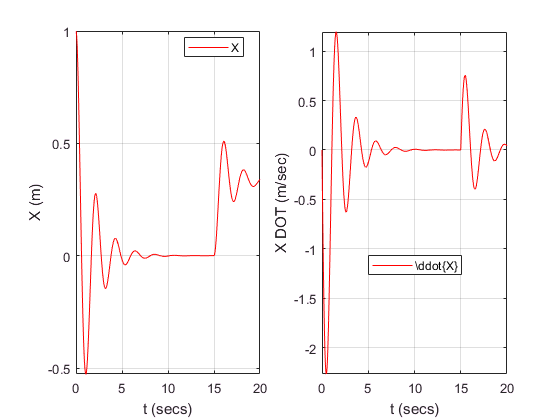

X_dot = Z(:,1); 
X     = Z(:,2);  

figure;
subplot(1,2,1);
   plot(T,X,'-r');      
                       xlabel('t (secs)'); ylabel('X (m)'); grid('on'); axis('tight');
                       legend('X', 'Location', 'best');
   %----------------------------------------------------------------------- 
subplot(1,2,2);
   plot(T,X_dot,'-r');  
                       xlabel('t (secs)'); ylabel('X DOT (m/sec)'); grid('on'); axis('tight');
                       legend('X DOT', 'Location', 'best');

# Next steps - part 1

If you found this tutorial on MATLAB interesting, have a look at the Simulink model called **bh_1dof_hello.slx**.  This model shows how Simulink and Simscape can be used to model and solve the same spring mass damper system ... but instead of writing lines of code, Simulink models are built using block diagrams.

In **Simulink**, here's how we model the ODE for the spring mass damper.  Note how we have 2 integrators which integrate from $\ddot{X} \rightarrow \dot{X}$ and then from $\dot{X} \rightarrow X$.  These integrators can be initialised by the system's initial conditions.

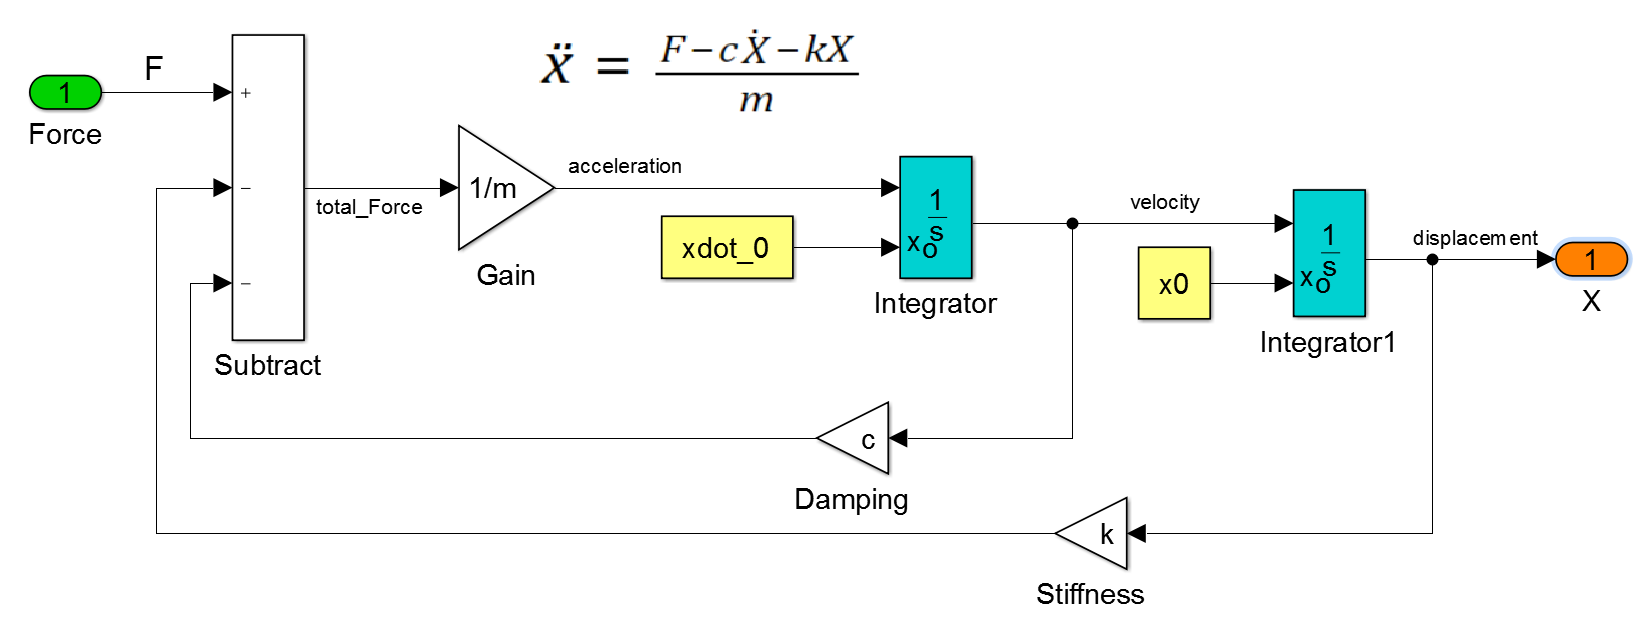

While in **Simscape**(which is still within the Simulink modelling environment), the spring mass damper model looks like this:

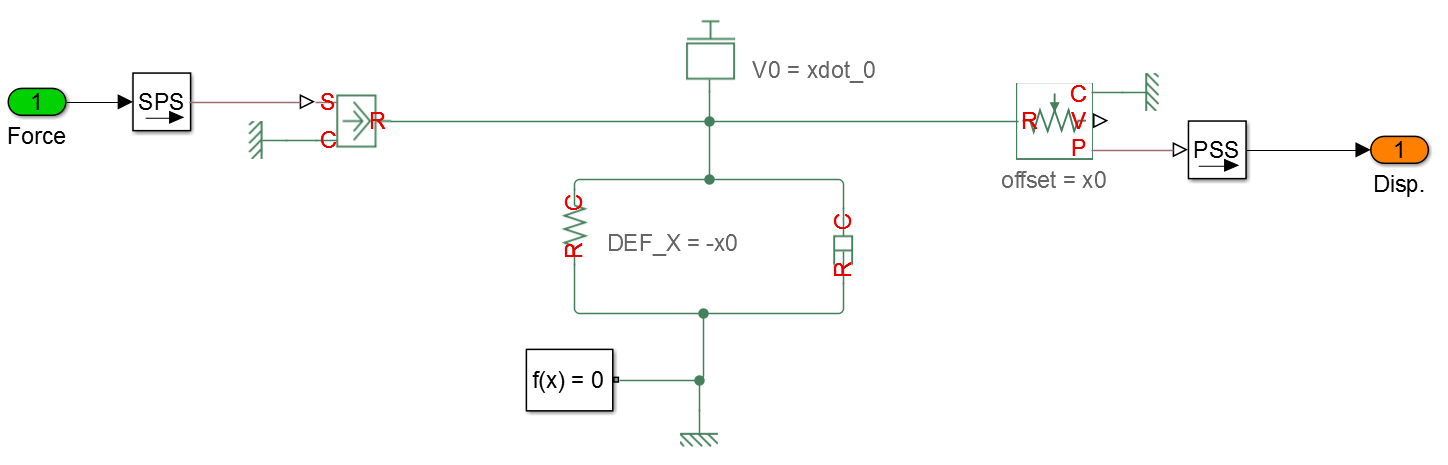

When you simulate these SIMULINK models, here's an example of a "scope" block that shows the excitation force *F(t)* and the spring's displacement *X(t):*